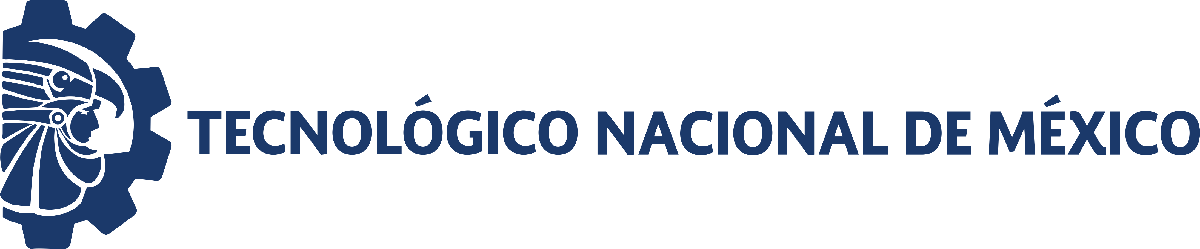                                 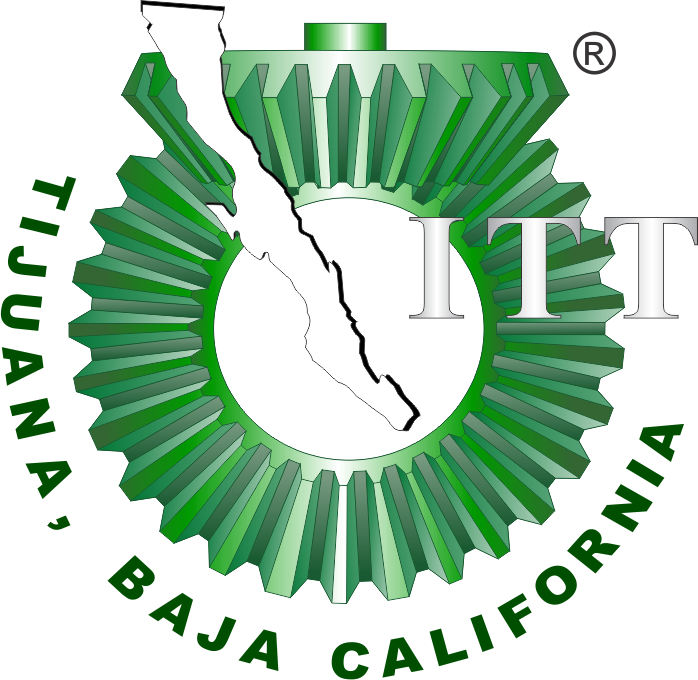

# Proyecto

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

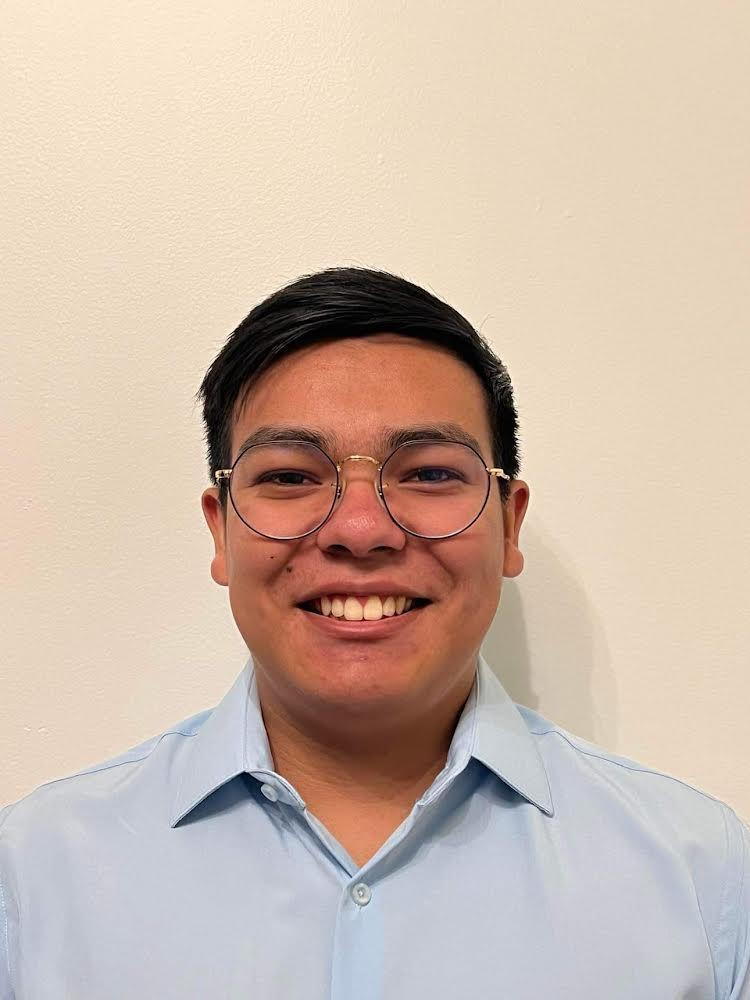

Nombre del alumno: **Alexander Torres Avila**

Número de control: **21212848**

Correo institucional: **L21212848@tectijuana.edu.mx**

Carrera: **Ing. Biomédica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation Data

## Data fitting 

clc; clear;close all; warning('off','all')

## Raw data 

sys = readmatrix(['DATA.xlsx']);
to = round(sys(:,1)); xo = sys(:,2); yo = sys(:,3); zo = sys(:,4);
alpha = 0.5;       beta = 0.01;
delta = 0.001;     gamma = 0.2;
P = [alpha, beta, delta, gamma];
T = array2table([to,xo,yo,zo],'VariableNames',{'t [time]','xo','yo','zo'}); disp(T)

    t [time]     xo        yo       zo  
    ________    _____    ______    _____

        0       0.517    19.939    0.281
        7        0.58    19.578    0.609
       14       0.726    18.678    1.063
       21       0.965    16.215    1.758
       28       1.282    14.005    2.752
       35       1.825    11.467    3.975
       42       2.473     8.096    4.895
       49       2.974     4.327    6.096
       56        3.43     1.287    7.152
       63       3.717     0.194    7.328
       70       3.829     0.056    7.232



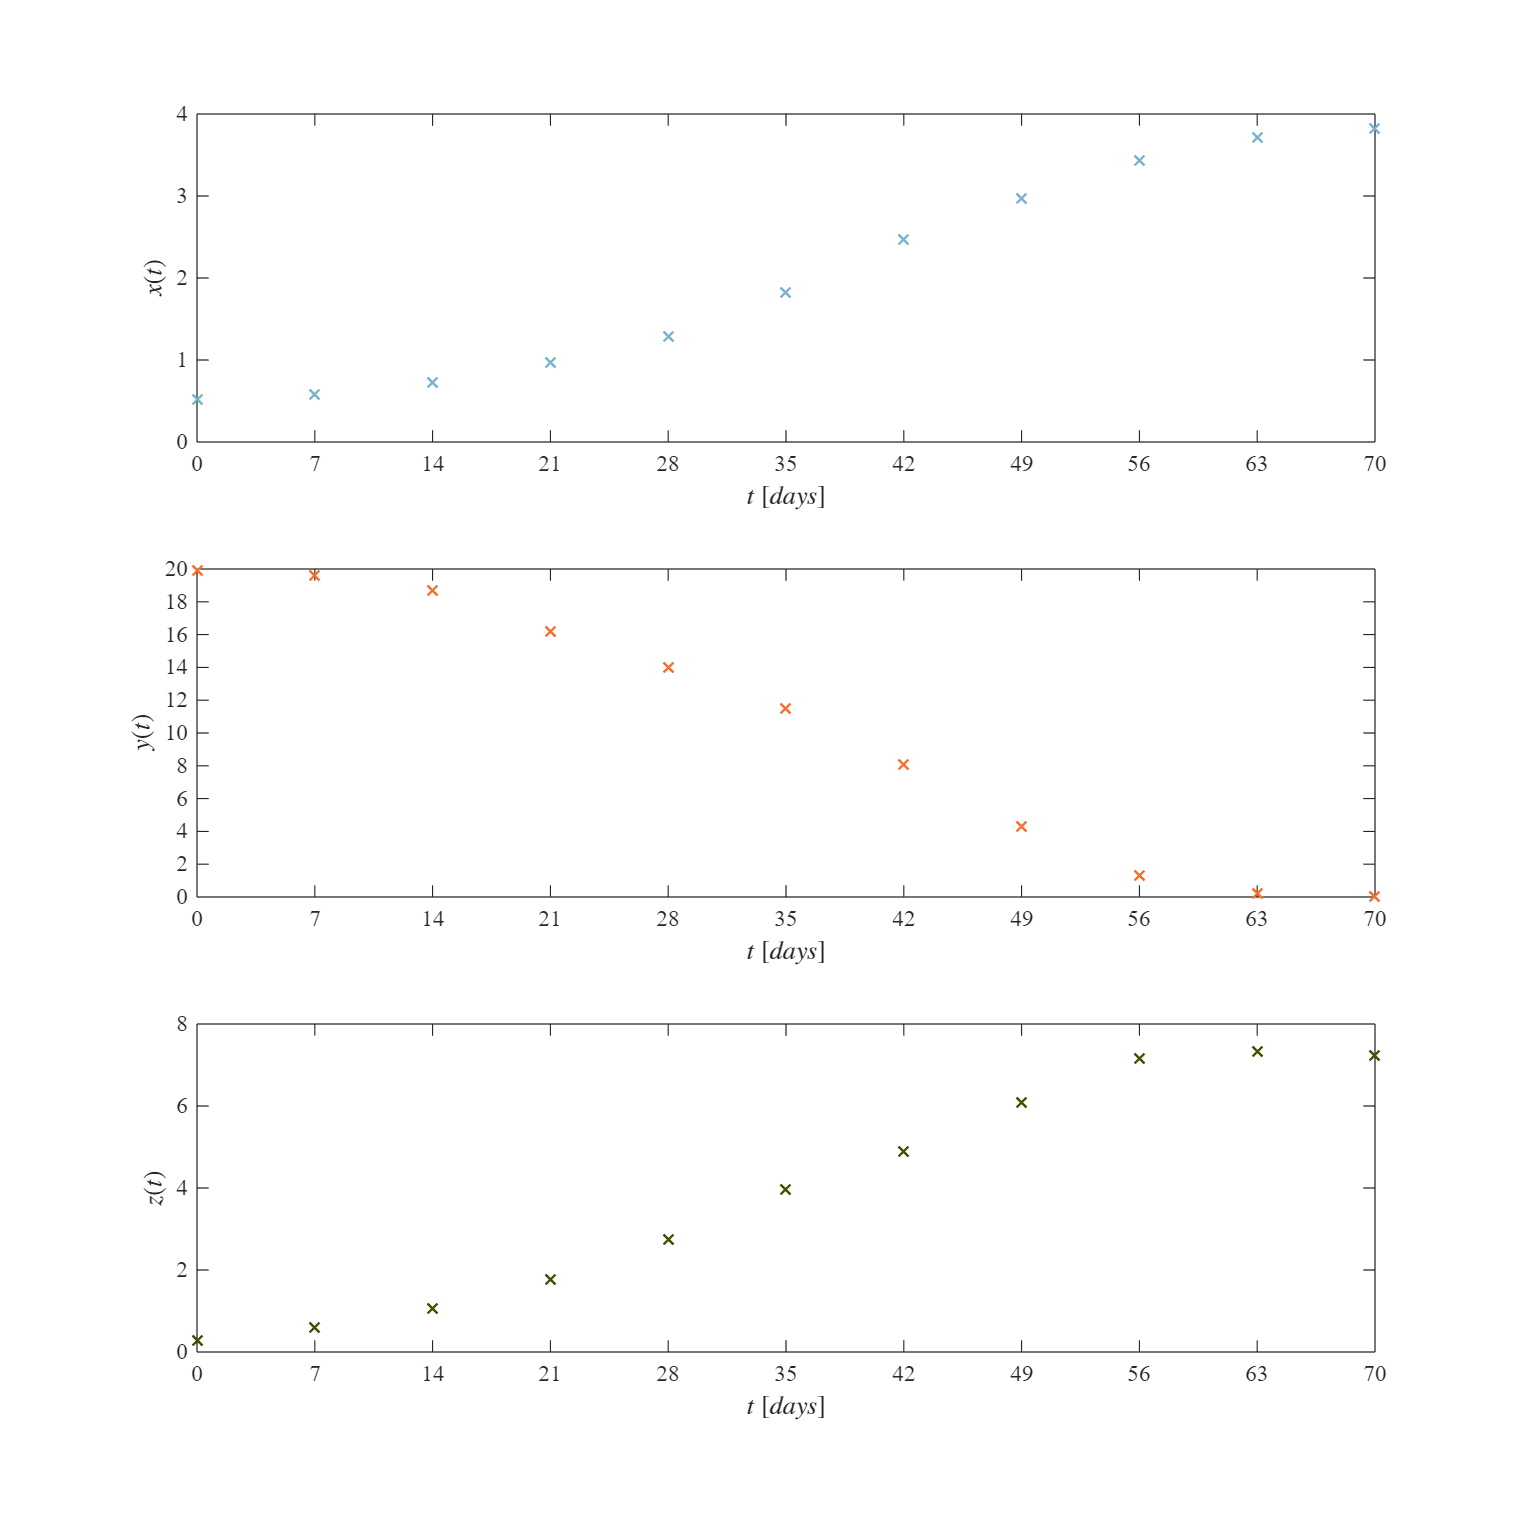

plotEDOs(to,xo,yo,zo,P,0);
exportgraphics(gcf,'Data.pdf', 'ContentType','Vector')

## Smooth data

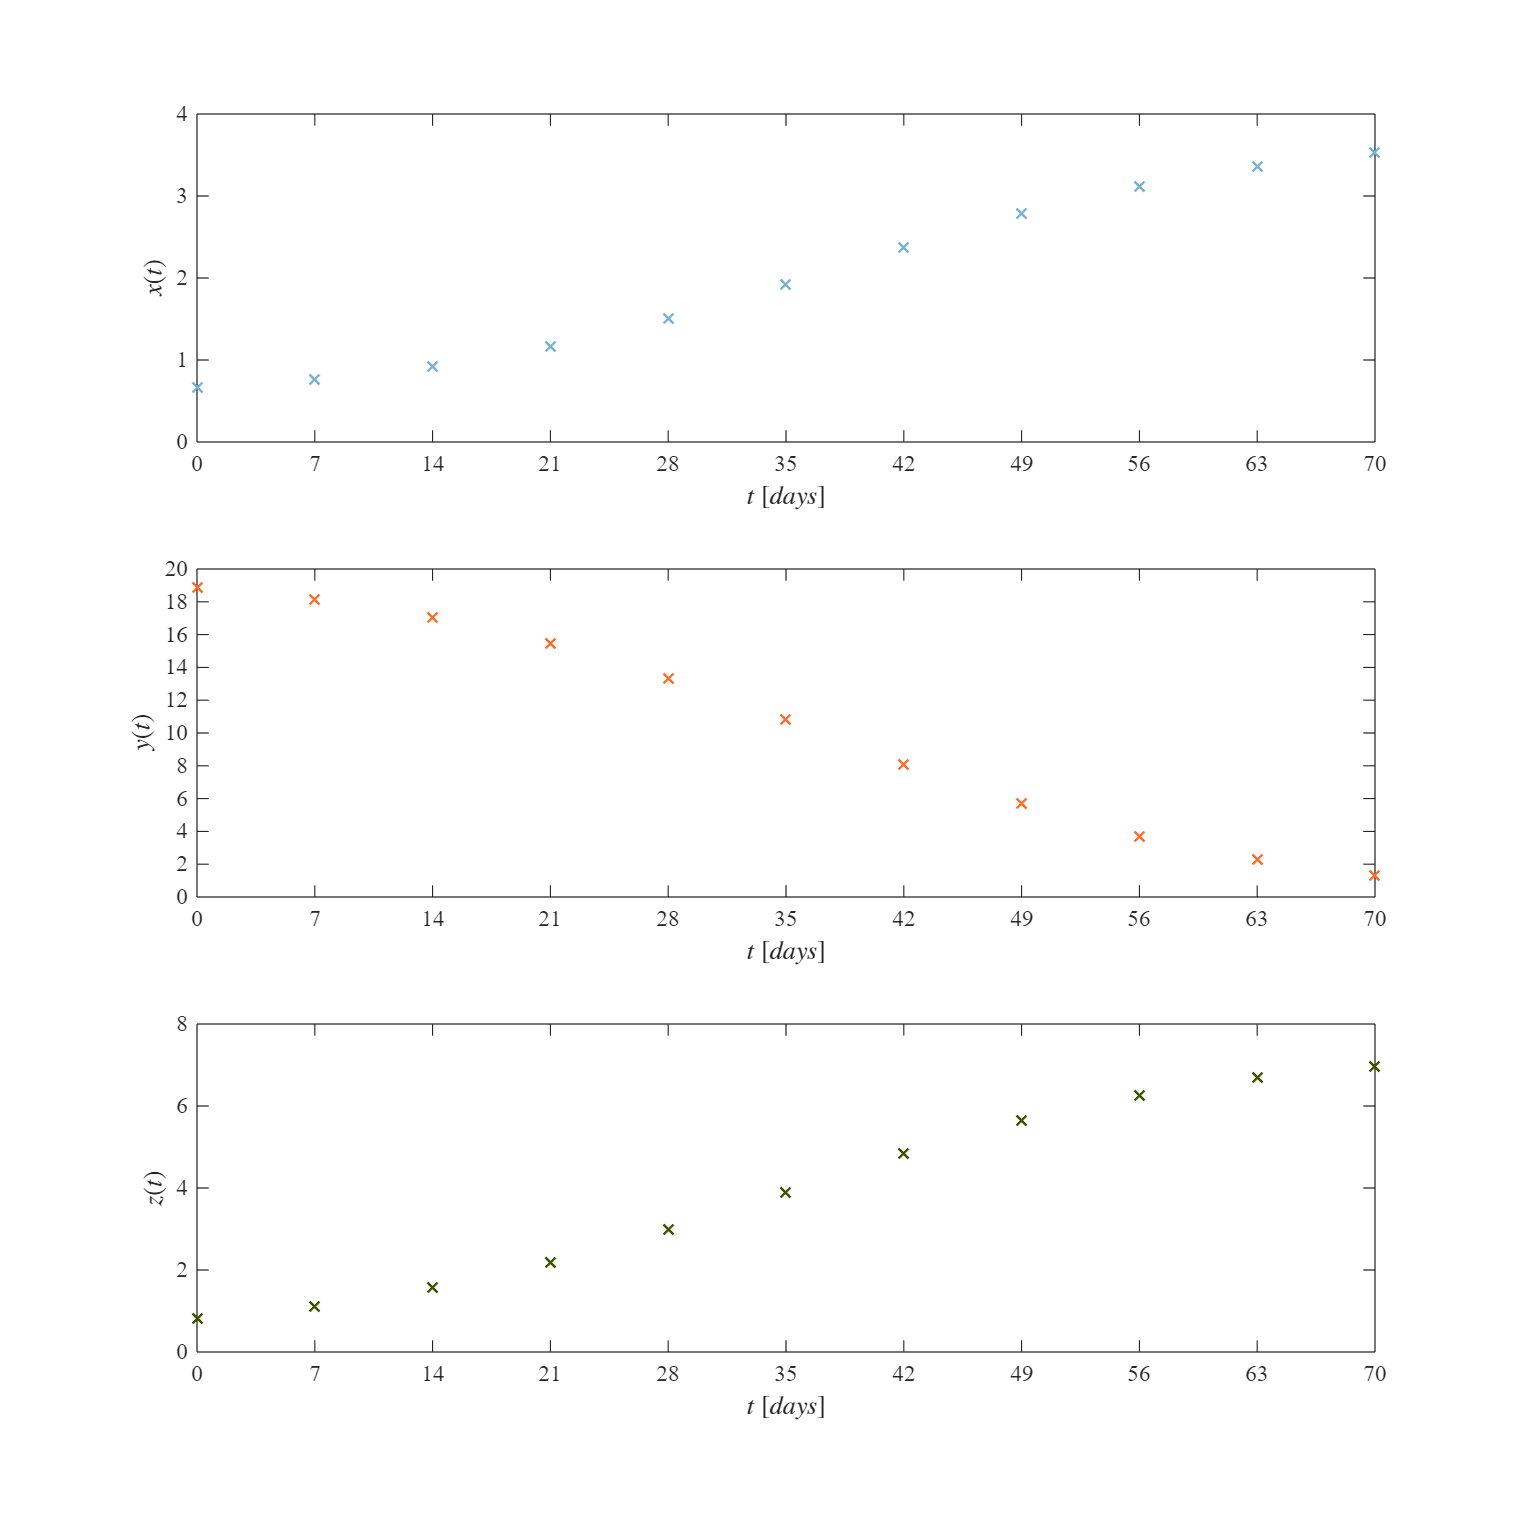

xo = smoothdata(xo, 'gaussian',10);
yo = smoothdata(yo, 'gaussian',10);
zo = smoothdata(zo, 'gaussian',10);
plotEDOsSmooth(to,xo,yo,zo,P,0);
exportgraphics(gcf,'Data (smooth).pdf', 'ContentType','Vector')

T = table(to(:), xo(:), yo(:), zo(:), ...
    'VariableNames', {'Time', 'X_smooth', 'Y_smooth', 'Z_smooth'});
writetable(T, 'DATA_SMOOTH.csv');


$$\dot{x} =\rho_1 \;x\;y\;z$$



$$\dot{y} =\rho_2 \;y-\rho_3 \;x\;y\;$$



$$\dot{z} =\rho_4 \;z-\rho_5 \;x\;z$$


## Nonlinear regression algorithm

clc; clear;close all;
P0 = [0.000651; 0.011; 0.0239; 0.0681; 0.018];

sys = readmatrix('DATA_SMOOTH.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
zo = sys(:,4);

[mdl, xa, ya, za] = fitting_model(to,xo,yo,zo,P0);

    Parameters     Estimate         SE           MoE                 CI95                Pvalue  
    __________    __________    __________    _________    ________________________    __________

     {'rho1'}     0.00086236    1.6037e-05    3.285e-05    0.00082951    0.00089521    8.3594e-30
     {'rho2'}       0.012917    0.00080589    0.0016508      0.011266      0.014567    1.2306e-15
     {'rho3'}       0.028268    0.00085201    0.0017453      0.026523      0.030013    5.0486e-24
     {'rho4'}       0.059893     0.0011082      0.00227      0.057623      0.062163    7.2602e-30
     {'rho5'}       0.015456    0.00076578    0.0015686      0.013887      0.017024    3.1951e-18


Sample size (n): 11
Parameters to be estimated (pars): 5
Degrees of freedom: 28
Significance level (alpha):

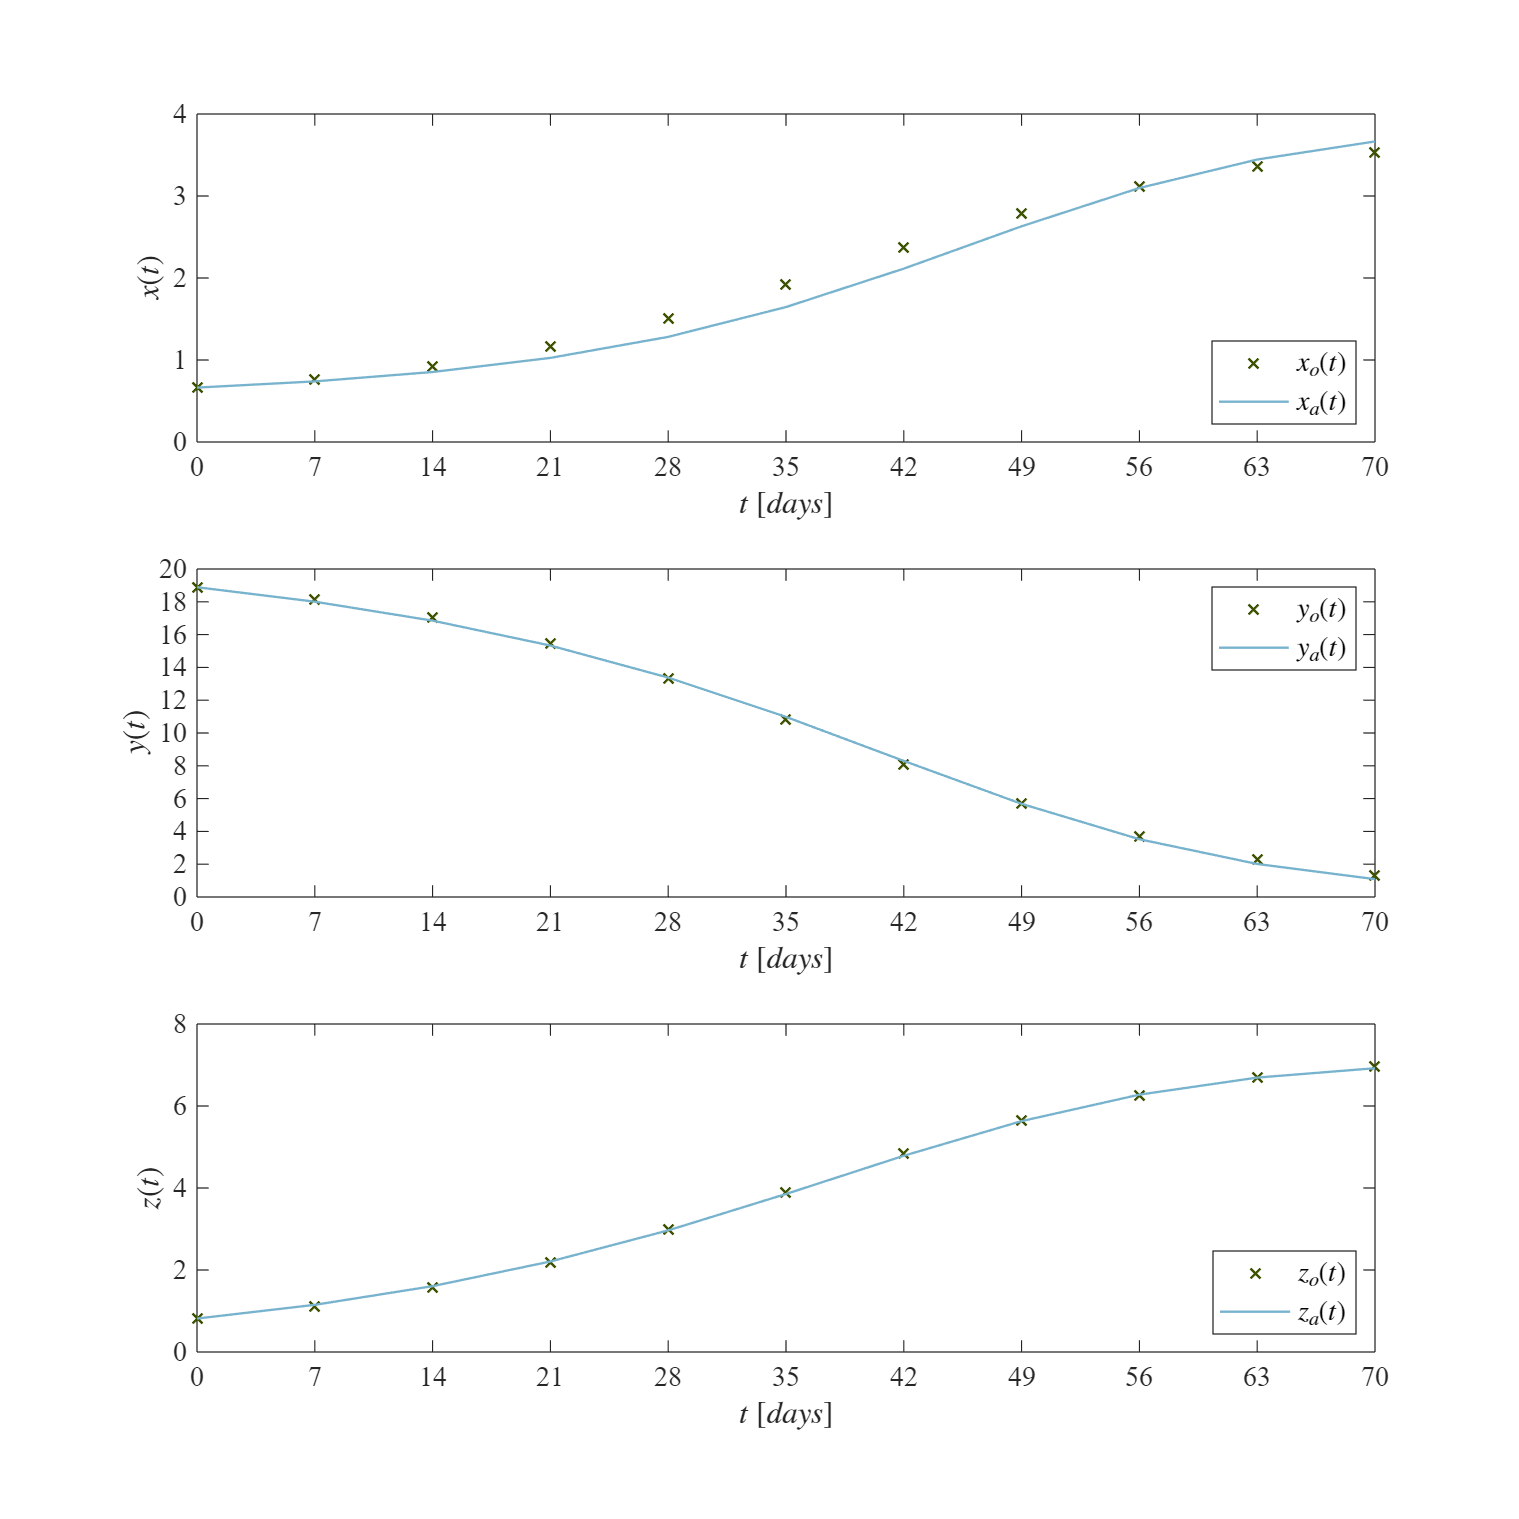

plotresults(to,[xo,xa],[yo,ya],[zo,za]); 
exportgraphics(gcf,'Nonlinear regression algorithm.pdf', 'ContentType','Vector')

## Equilibrium points and Jacobian matrix

clear; close all; clc
syms x y z rho1 rho2 rho3 rho4 rho5
  dx = rho1*x*y*z;
  dy = rho2*y - rho3*x*y;
  dz = rho4*z - rho5*x*z;
J = jacobian([dx,dy,dz],[x,y,z]);
fprintf('Jacobian matrix of the system:'); disp(J)

Jacobian matrix of the system:

$$\left(\begin{array}{ccc} \rho_{1}\,y\,z & \rho_{1}\,x\,z & \rho_{1}\,x\,y\\ -\rho_{3}\,y & \rho_{2}-\rho_{3}\,x & 0\\ -\rho_{5}\,z & 0 & \rho_{4}-\rho_{5}\,x \end{array}\right)$$

dx = rho1*x*y*z==0;
dy = rho2*y - rho3*x*y==0;
dz = rho4*z - rho5*x*z==0;
edos = solve([dx,dy,dz],[x,y,z]);
fprintf(['The system has ', num2str(length(edos.x)), ' equilibrium points.'])

The system has 3 equilibrium points.

equilibria = solve([dx,dy,dz],[x,y,z]);
for i = 1:3
    xe(i,1) = simplify(equilibria.x(i));
    ye(i,1) = simplify(equilibria.y(i));
    ze(i,1) = simplify(equilibria.z(i));

    fprintf(['Equilibrium points of the system: ', num2str(i), '\n'])
    fprintf(['x', num2str(i), '=', char(xe(i,1)), '\n']);
    fprintf(['y', num2str(i), '=', char(ye(i,1)), '\n']);
    fprintf(['z', num2str(i), '=', char(ze(i,1)), '\n']);
end

Equilibrium points of the system: 1


x1=rho2/rho3


y1=0


z1=0


Equilibrium points of the system: 2


x2=rho4/rho5


y2=0


z2=0


Equilibrium points of the system: 3


x3=0


y3=0


z3=0


X0 = edos.x(1); Y0= edos.y(1); Z0 = edos.z(1);
X1 = edos.x(2); Y1= edos.y(2); Z1 = edos.z(2);
X2 = edos.x(3); Y2= edos.y(3); Z2 = edos.z(3);
syms x0 y0 z0 x1 y1 z1 x2 y2 z2
fprintf('Equilibrium points of the system:'); disp([x0,y0,z0,X0,Y0,Z0]); disp([x1,y1,z1,X1,Y1,Z1]); disp([x2,y2,z2,X2,Y2,Z2]); 

Equilibrium points of the system:

$$\left(\begin{array}{cccccc} x_{0} & y_{0} & z_{0} & \frac{\rho_{2}}{\rho_{3}} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{1} & y_{1} & z_{1} & \frac{\rho_{4}}{\rho_{5}} & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{2} & y_{2} & z_{2} & 0 & 0 & 0 \end{array}\right)$$

clear rho2 rho3 rho4 rho5

rho2 = 0.00788;
rho3 = 0.00195;
rho4 = 0.00778;
rho5 = 0.000428;

X0_num = rho2 / rho3;
X1_num = rho4 / rho5;

fprintf('(x0,y0,z0) = (%.4f, 0, 0)\n', X0_num);

(x0,y0,z0) = (4.0410, 0, 0)


fprintf('(x1,y1,z1) = (%.4f, 0, 0)\n', X1_num);

(x1,y1,z1) = (18.1776, 0, 0)


fprintf('(x2,y2,z2) = (0, 0, 0)\n');

(x2,y2,z2) = (0, 0, 0)


## Local estability

clc; clear;

rho1 = 0.000651;  
rho2 = 0.00788;
rho3 = 0.00195;
rho4 = 0.00778;
rho5 = 0.000428;

syms x y z
dx = rho1*x*y*z == 0;
dy = rho2*y - rho3*x*y == 0;
dz = rho4*z - rho5*x*z == 0;
edos = solve([dx, dy, dz], [x, y, z]);

X = double([edos.x]);
Y = double([edos.y]);
Z = double([edos.z]);

idx_rho2 = find(abs(X - (rho2/rho3)) < 1e-3);   
idx_rho4 = find(abs(X - (rho4/rho5)) < 1e-3);   
idx_zero = find(abs(X) < 1e-6);                

x0 = X(idx_rho2); y0 = Y(idx_rho2); z0 = Z(idx_rho2);
x1 = X(idx_rho4); y1 = Y(idx_rho4); z1 = Z(idx_rho4);
x2 = X(idx_zero); y2 = Y(idx_zero); z2 = Z(idx_zero);

x = [x0; x1; x2];
y = [y0; y1; y2];
z = [z0; z1; z2];

var = {'(x0,y0,z0)'; '(x1,y1,z1)'; '(x2,y2,z2)'};

Equilibria = table(x, y, z, 'RowNames', var);
Equilibria.Properties.VariableNames = {'xe', 'ye', 'ze'};

fprintf('Equilibrium points of the system:\n');disp(Equilibria)

Equilibrium points of the system:
                    xe      ye    ze
                  ______    __    __

    (x0,y0,z0)     4.041    0     0 
    (x1,y1,z1)    18.178    0     0 
    (x2,y2,z2)         0    0     0 



L = zeros(length(x), 3); 

for i = 1:length(x)
    J = [ rho1*y(i)*z(i),       rho1*x(i)*z(i),       rho1*x(i)*y(i);
         -rho3*y(i),            rho2 - rho3*x(i),     0;
         -rho5*z(i),            0,                    rho4 - rho5*x(i) ];
    
    fprintf('\nJacobian matrix at (x%d, y%d):\n', i-1, i-1);
    disp(J)
    
    L(i,:) = eig(J).';
end


Jacobian matrix at (x0, y0):


         0         0         0
         0         0         0
         0         0    0.0061




Jacobian matrix at (x1, y1):


         0         0         0
         0   -0.0276         0
         0         0   -0.0000




Jacobian matrix at (x2, y2):


         0         0         0
         0    0.0079         0
         0         0    0.0078



L1 = L(:,1); 
L2 = L(:,2);
L3 = L(:,3);
Lambdas = table(L1, L2, L3, 'RowNames', var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:');disp(Lambdas)

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                     L1            L2            L3    
                  _________    ___________    _________

    (x0,y0,z0)            0              0    0.0060504
    (x1,y1,z1)    -0.027566    -8.6736e-19            0
    (x2,y2,z2)            0        0.00778      0.00788



##  **Model Assumptions**

The system is assumed to represent the dynamic interaction between three cellular populations present in a specific biological environment, such as the hepatic microenvironment during an antitumor immune response. The three considered populations are:

- **Cancer cells (x):** These cells are assumed to proliferate in the presence of functional healthy cells (y), and may initially benefit from immune activity (z), since certain inflammatory stimuli can induce proliferative changes.

- **Healthy cells (y):** These regenerate naturally, but their population decreases due to damage caused by tumor cells. The destruction is modeled as an interaction dependent on both populations (x·y), following a resource consumption pattern.

- **Effector immune cells (z):** Such as CD8+ T lymphocytes, these cells are activated and proliferate initially in response to the presence of tumor antigens, but over time they may be inhibited or exhausted by the tumor’s own immunosuppressive mechanisms, modeled by the term -ρ₅ x·z.

It is assumed that:

- The environment is closed (no inflow or outflow of external cells).

- The interaction rates between populations are proportional to the product of the involved quantities (Lotka-Volterra-type model).

- There are no spatial effects or mutations in the populations.

- Direct treatments (chemotherapy or radiotherapy) are not considered, although the model can be adapted to include them.

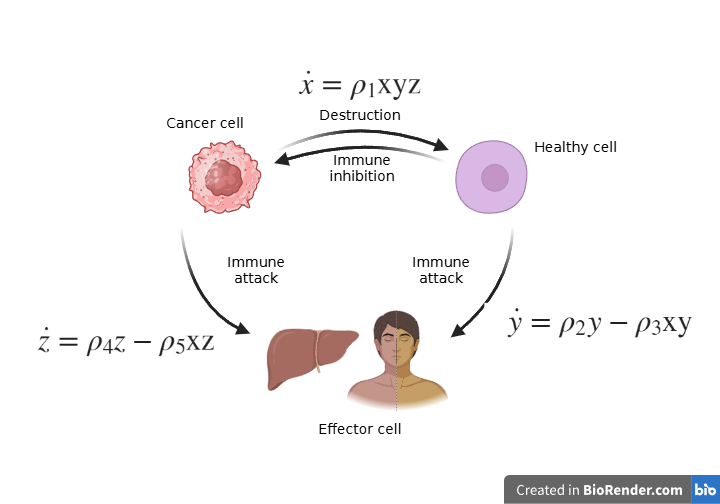

## Prediction 2t

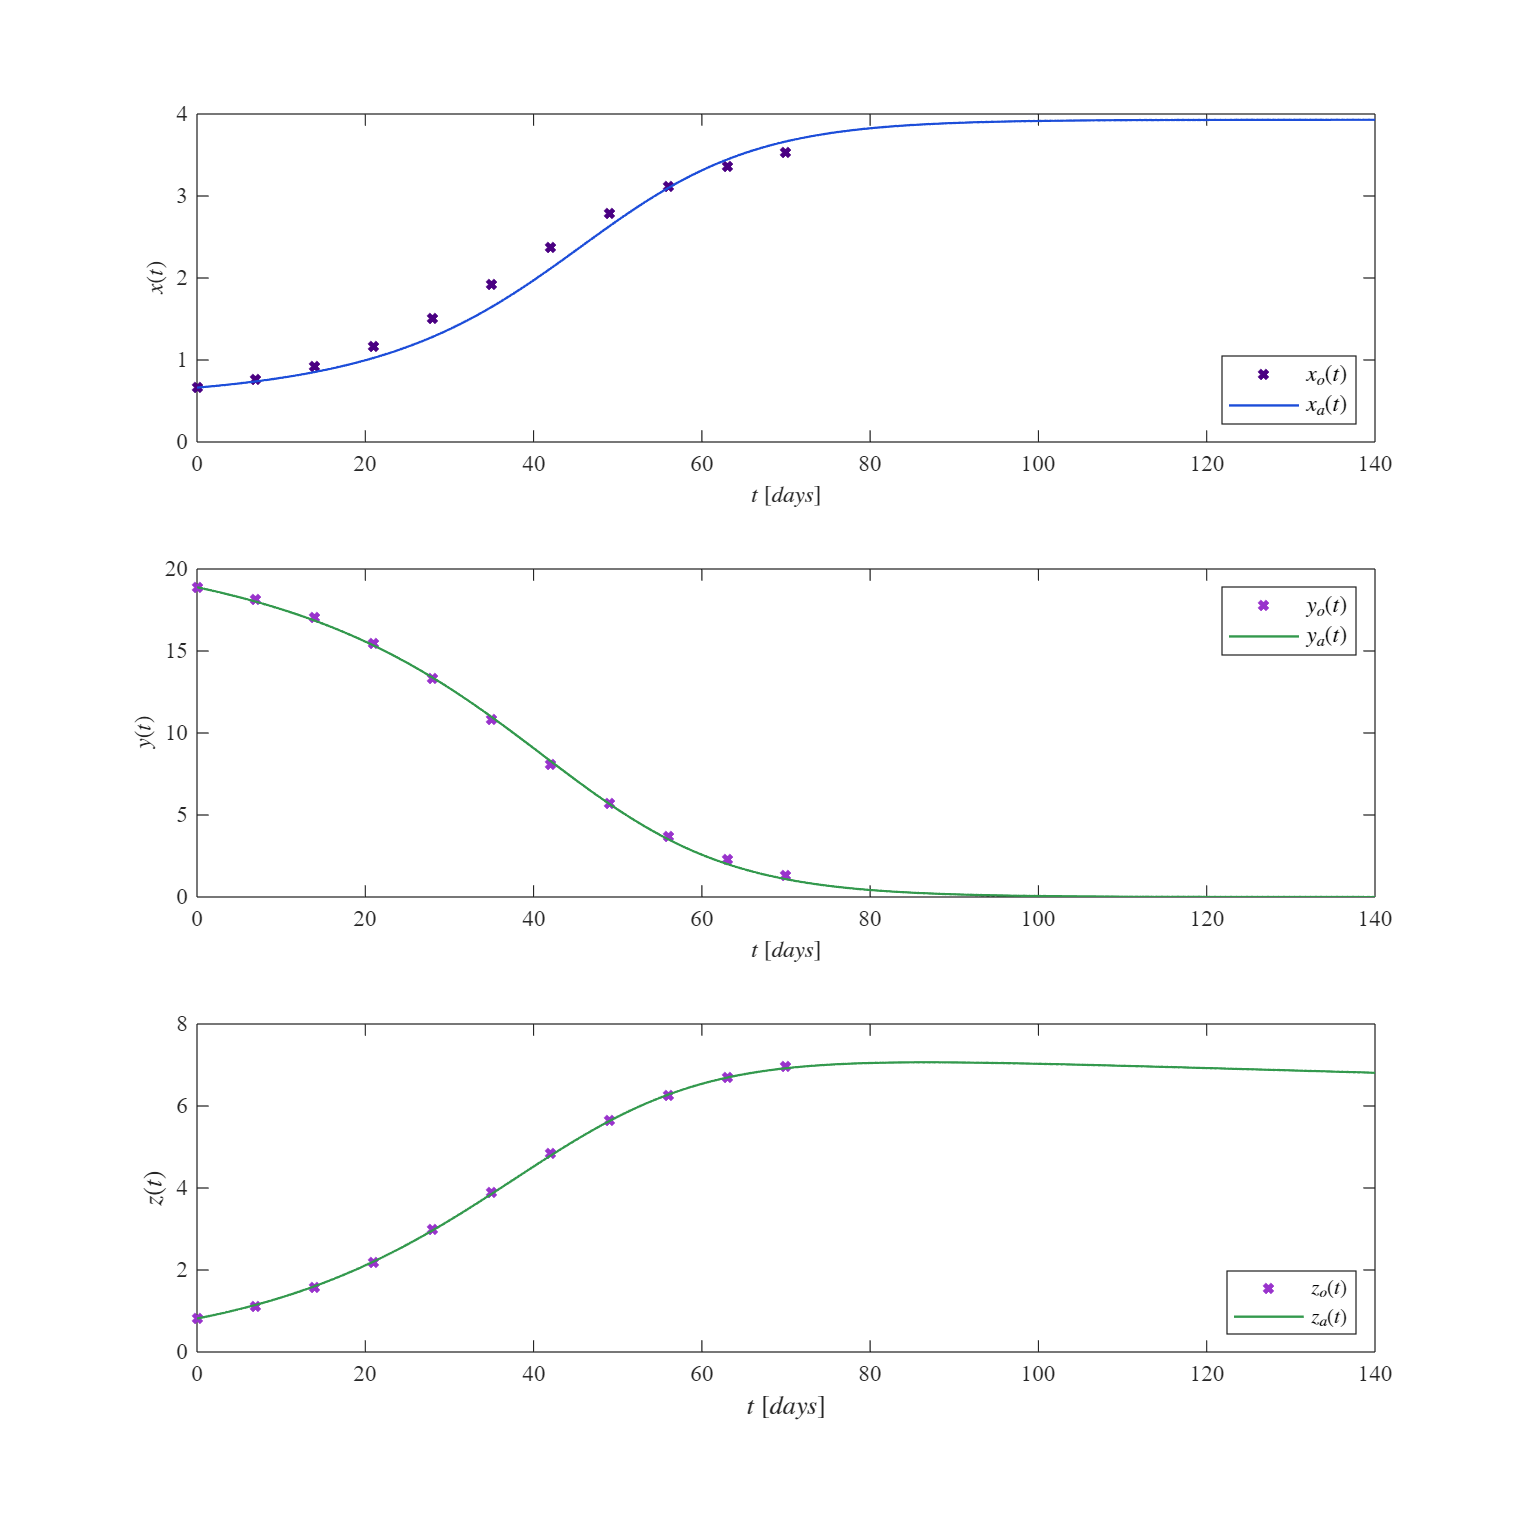

clc; clear; close all;
sys = readmatrix('DATA_SMOOTH.csv');
to = sys(:,1);
x1o = sys(:,2);
y1o = sys(:,3);
z1o = sys(: ,4);
T2 = array2table([to,x1o,y1o,z1o], 'VariableNames', {'Tiempo', 'xo(t)', 'yo(t)', 'zo(t)'});
P0 = [0.000651; 0.011; 0.0239; 0.0681; 0.018];
[t_ext, xa, ya, za] = predict(to, x1o, y1o, z1o, P0);

plotext(t_ext,to,x1o,xa,y1o,ya,z1o,za);
exportgraphics(gcf,'Predict 2t.pdf', 'ContentType','Vector')

## Conclusion and discussion of results

The proposed mathematical model describes the nonlinear interaction between three cellular populations: pathological cells $x\left(t\right)$, healthy cells $y\left(t\right)$, and effector cells of the immune system $z\left(t\right)$. Through numerical simulation and graphical representation of their trajectories over time, an oscillatory dynamic is observed in all three populations, suggesting a cyclical behavior characteristic of predator-prey or competitive systems with feedback.

In particular, the healthy cells exhibit a damped periodic oscillation, indicating regeneration following periods of pathological aggression. The effector immune cells show peaks of activation followed by decline phases, which can be interpreted as an immune response stimulated by the presence of tumors but later inhibited, possibly due to cellular exhaustion. Meanwhile, the pathological cells display a growth and reduction pattern that depends both on the amount of healthy tissue and the immune pressure.

From a theoretical standpoint, the system satisfies the conditions of positivity, ensuring that the solutions remain within the biologically valid domain. This is crucial in models of cellular populations where negative values have no physiological interpretation.

The results obtained suggest that the modeled system can adequately capture the mechanisms of tumor proliferation, tissue damage, and immune response, and that its complex behavior can serve as a basis for exploring clinical scenarios such as immunotherapy, cyclic treatments, or tumor progression under immunosuppressive conditions.

In future studies, this model could be enhanced by including treatment terms, antigen dynamics, or more complex adaptive responses of the immune system.

## Functions 

### Solutions and trajectories

function plotEDOs(t, x, y, z, P, dt)
    set(figure(1), 'Color','w');
    
    % Colores personalizados
    c1 = [120, 179, 206]/255;
    c2 = [249, 110, 42]/255;
    c3 = [61, 83, 0]/255;
    
    % Tamaño de figura
    set(gcf, 'Units','Centimeters', 'Position', [2, 2, 100, 100]);

    
    % Parámetros (no usados directamente pero podrían ser útiles)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    % ------------------------ x(t)
    subplot(3, 1, 1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, x, 'x', 'LineWidth', 1, 'Color', c1);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:7:70);
    ylim([0 4]); yticks(0:1:4);

    % ------------------------ y(t)
    subplot(3, 1, 2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, y, 'x', 'LineWidth', 1, 'Color', c2);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:7:70);
    ylim([0 20]); yticks(0:2:20);

    % ------------------------ z(t)
    subplot(3, 1, 3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, z, 'x', 'LineWidth', 1, 'Color', c3);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:7:70);
    ylim([0 8]); yticks(0:2:8);
end

function plotEDOsSmooth(t, x, y, z, P, dt)
    set(figure(2), 'Color','w');
    
    % Colores personalizados
    c1 = [120, 179, 206]/255;
    c2 = [249, 110, 42]/255;
    c3 = [61, 83, 0]/255;
    
    % Tamaño de figura
    set(gcf, 'Units','Centimeters', 'Position', [2, 2, 100, 100]);

    
    % Parámetros (no usados directamente pero podrían ser útiles)
    alpha = P(1); beta = P(2); delta = P(3); gamma = P(4);

    % ------------------------ x(t)
    subplot(3, 1, 1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, x, 'x', 'LineWidth', 1, 'Color', c1);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$x(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:7:70);
    ylim([0 4]); yticks(0:1:4);

    % ------------------------ y(t)
    subplot(3, 1, 2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, y, 'x', 'LineWidth', 1, 'Color', c2);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$y(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:7:70);
    ylim([0 20]); yticks(0:2:20);

    % ------------------------ z(t)
    subplot(3, 1, 3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(t, z, 'x', 'LineWidth', 1, 'Color', c3);
    xlabel('$t$ $[days]$', 'Interpreter', 'latex');
    ylabel('$z(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:7:70);
    ylim([0 8]); yticks(0:2:8);
end

### Nonlineal regression algorithm

function [mdl, xa, ya, za] = fitting_model(to, xo, yo, zo, P0)
    % Variables iniciales
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    
    % Concatenar observaciones
    fo = [xo; yo; zo];  
    to = [to; to; to];  % Repetir para cada variable

    % Modelo de ajuste no lineal
    function xi = AjusteAproximado(P, t)
        t = t(:);  % Asegurar vector columna
        dt = 1E-2;
        time = (0:dt:max(t))';
        n = length(time)-1;

        rho1 = P(1); rho2 = P(2); rho3 = P(3);
        rho4 = P(4); rho5 = P(5);

        % Inicializar soluciones
        x = zeros(n+1,1); x(1) = x0;
        y = zeros(n+1,1); y(1) = y0;
        z = zeros(n+1,1); z(1) = z0;

        for i = 1:n
            [dx, dy, dz] = f(x(i), y(i), z(i));
            xn = x(i) + dx*dt;
            yn = y(i) + dy*dt;
            zn = z(i) + dz*dt;
            [dxn, dyn, dzn] = f(xn, yn, zn);
            x(i+1) = x(i) + (dx + dxn)*dt/2;
            y(i+1) = y(i) + (dy + dyn)*dt/2;
            z(i+1) = z(i) + (dz + dzn)*dt/2;
        end

        % Sistema de ecuaciones
        function [dx, dy, dz] = f(x, y, z)
            dx = rho1*x*y*z;
            dy = rho2*y - rho3*x*y;
            dz = rho4*z - rho5*x*z;
        end

        % Separar t en tres bloques
        n_t = length(t)/3;
        t_x = t(1:n_t);
        t_y = t(n_t+1:2*n_t);
        t_z = t(2*n_t+1:end);

        xi = interp1(time, x, t_x, 'linear', 'extrap');
        yi = interp1(time, y, t_y, 'linear', 'extrap');
        zi = interp1(time, z, t_z, 'linear', 'extrap');

        % Verifica que no existan valores inválidos
        if any(isnan([xi; yi; zi])) || any(isinf([xi; yi; zi]))
            error('AjusteAproximado ha generado NaN o Inf. Revisa dt, P0, o límites del sistema.');
        end

        xi = [xi; yi; zi];  % Vector final concatenado
    end

    % Ajuste con fitnlm
    mdl = fitnlm(to, fo, @AjusteAproximado, P0);

    % Extracción de resultados
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    Pvalue = table2array(mdl.Coefficients(:,4));
    CI95 = coefCI(mdl, 0.05);
    dof = mdl.DFE;
    alpha = 0.05;
    tval = tinv(1 - alpha/2, dof);
    MoE = SE * tval;

    Parameters = {'rho1','rho2','rho3','rho4','rho5'}';
    fit = table(Parameters, Estimate, SE, MoE, CI95, Pvalue);
    disp(fit)

    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P0))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student values: ', num2str(tval)])
    fprintf(['\nAdjusted R-squared: ', num2str(mdl.Rsquared.Adjusted)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])

    % Obtener parámetros estimados y valores ajustados
    Pest = Estimate;
    t_unique = to(1:length(xo));  % vector de tiempo original (no triplicado)

    ajuste = AjusteAproximado(Pest, [t_unique; t_unique; t_unique]);
    xa = ajuste(1:length(t_unique));
    ya = ajuste(length(t_unique)+1 : 2*length(t_unique));
    za = ajuste(2*length(t_unique)+1 : end);
end


function plotresults(t,x,y,z)
    figure(3); clf;
    set(gcf, 'Color', 'w', 'Units', 'Centimeters', 'Position', [2, 2, 100, 100]); % figura más vertical

    c1 = [120, 179, 206] / 255; 
    c3 = [61, 83, 0] / 255; 
    FS = 12;

    % === x(t) ===
    subplot(3,1,1)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold on; box on; grid off;
    plot(t, x(:,1), 'x', 'LineWidth', 1, 'Color', c3)
    plot(t, x(:,2), '-', 'LineWidth', 1, 'Color', c1)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$x(t)$', 'Interpreter', 'latex')
    legend('$x_o(t)$','$x_a(t)$','Interpreter','latex','FontSize',FS,'Location','SouthEast')
    xlim([0 70]); xticks(0:7:70);
    ylim([0 4]); yticks(0:1:4);

    % === y(t) ===
    subplot(3,1,2)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold on; box on; grid off;
    plot(t, y(:,1), 'x', 'LineWidth', 1, 'Color', c3)
    plot(t, y(:,2), '-', 'LineWidth', 1, 'Color', c1)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$y(t)$', 'Interpreter', 'latex')
    legend('$y_o(t)$','$y_a(t)$','Interpreter','latex','FontSize',FS,'Location','NorthEast')
    xlim([0 70]); xticks(0:7:70);
    ylim([0 20]); yticks(0:2:20);

    % === z(t) ===
    subplot(3,1,3)
    set(gca, 'FontName', 'Times New Roman', 'FontSize', FS)
    hold on; box on; grid off;
    plot(t, z(:,1), 'x', 'LineWidth', 1, 'Color', c3)
    plot(t, z(:,2), '-', 'LineWidth', 1, 'Color', c1)
    xlabel('$t$ $[days]$', 'Interpreter', 'latex')
    ylabel('$z(t)$', 'Interpreter', 'latex')
    legend('$z_o(t)$','$z_a(t)$','Interpreter','latex','FontSize',FS,'Location','SouthEast')
    xlim([0 70]); xticks(0:7:70);
    ylim([0 8]); yticks(0:2:8);
end


### 2t prediction

function [t_ext, xa, ya, za] = predict(to, xo, yo, zo, P0)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to_concat = [to; to; to];
    fo = [xo; yo; zo];
    N = 2;

    function fi = model(P, t)
        rho1 = P(1); rho2 = P(2); rho3 = P(3);
        rho4 = P(4); rho5 = P(5);

        dt = 1E-1;
        t_input = reshape(t, [], 3); 
        t_input = t_input(:,1);
        tmax = N * max(t_input);
        time = (0:dt:tmax)';

        n = length(time);
        x = zeros(n,1); x(1) = x0;
        y = zeros(n,1); y(1) = y0;
        z = zeros(n,1); z(1) = z0;

        for i = 1:n-1
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = rho1*x*y*z;
            dy = rho2*y - rho3*x*y;
            dz = rho4*z - rho5*x*z;
        end

        % Interpolación solo para los puntos del conjunto de entrenamiento
        xi = zeros(length(t_input),1);
        yi = zeros(length(t_input),1);
        zi = zeros(length(t_input),1);
        for j = 1:length(t_input)
            k = abs(time - t_input(j)) < 1E-9;
            xi(j) = x(k);
            yi(j) = y(k);
            zi(j) = z(k);
        end
        fi = [xi; yi; zi];
    end

    t2 = fitnlm(to_concat, fo, @model, P0);
    P_fit = t2.Coefficients.Estimate;

    dt = 1E-1;
    tmax_ext = N * max(to);
    t_ext = (0:dt:tmax_ext)';

    function [x, y, z] = simulate(P, t)
        rho1 = P(1); rho2 = P(2); rho3 = P(3);
        rho4 = P(4); rho5 = P(5);

        x = zeros(length(t),1); x(1) = x0;
        y = zeros(length(t),1); y(1) = y0;
        z = zeros(length(t),1); z(1) = z0;

        for i = 1:length(t)-1
            [fx,fy,fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn,fyn,fzn] = f(xn,yn,zn);

            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = rho1*x*y*z;
            dy = rho2*y - rho3*x*y;
            dz = rho4*z - rho5*x*z;
        end
    end

    [xa, ya, za] = simulate(P_fit, t_ext);
end

function plotext(t_ext,to,x1o,x,y1o,y,z1o,z)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2, 2, 100, 100])
    
    c1 = [0.11, 0.30, 0.85]; c2 = [0.20, 0.60, 0.30];
    c3 = [0.85, 0.25, 0.30]; c4 = [0.95, 0.80, 0.20]; 
    m1 = [0.29, 0.00, 0.51]; m2 = [0.60, 0.20, 0.80];
    m3 = [0.73, 0.33, 0.83];

    subplot(3,1,1)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(to,x1o,'x','MarkerSize',5,'LineWidth',2,'Color',m1)
    plot(t_ext,x,'-','LineWidth',1,'Color',c1)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x(t)$','Interpreter','latex')
    L = legend('$x_o(t)$','$x_a(t)$');
    set(L,'Interpreter','latex','Location','SouthEast','Box','on')

    subplot(3,1,2)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(to,y1o,'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(t_ext,y,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$y(t)$','Interpreter','latex')
    L = legend('$y_o(t)$','$y_a(t)$');
    set(L,'Interpreter','latex','Location','NorthEast','Box','on')

    subplot(3,1,3)
    set(gca,'FontName','Time New Roman'); fontsize(10,'points')
    hold on; box on; grid off;
    plot(to,z1o,'x','MarkerSize',5,'LineWidth',2,'Color',m2)
    plot(t_ext,z,'-','LineWidth',1,'Color',c2)
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$z(t)$','Interpreter','latex')
    L = legend('$z_o(t)$','$z_a(t)$');
    set(L,'Interpreter','latex','Location','SouthEast','Box','on')
    %sgtitle('Prediction 2t');
end